%%% this is complete single script which includes all ML models:

%% 1.


data = readtable("cleaned2_network_data.xlsx");

lat =str2double(data.Lattitude);
lon = str2double(data.Longitude);
rsrp = str2double(data.RSRP_54_); % Replace with the actual column name

%F = scatteredInterpolant(lon, lat, rsrp, 'natural', 'none');
F = scatteredInterpolant(lon,lat,rsrp,'linear','nearest');

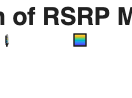

% Define Grid for Interpolation
lonGrid = linspace(min(lon), max(lon), 100);
latGrid = linspace(min(lat), max(lat), 100);
[LonGrid, LatGrid] = meshgrid(lonGrid, latGrid);

% Perform Interpolation
RSRP_Grid = F(LonGrid, LatGrid);

% Visualize the Interpolated Surface
figure;
surf(LonGrid, LatGrid, RSRP_Grid);
shading interp;
colorbar;
xlabel('Longitude');
ylabel('Latitude');
zlabel('Interpolated RSRP');
title('Geospatial Interpolation of RSRP Measurements');


rng(1); % For reproducibility



% Convert all variables to numeric if necessary (handles text or cell arrays)
dataNumeric = varfun(@(x) str2double(string(x)), data);

% Clean the data: Remove rows with -999 or missing values
%dataNumeric = dataNumeric(~any(dataNumeric.Variables == -999 | isnan(dataNumeric.Variables), 2), :);

% Extract predictors (features) and target (RSRP)
predictorVars = dataNumeric(:, setdiff(dataNumeric.Properties.VariableNames, {'Fun_RSRP_54_'}));
targetVar = dataNumeric.Fun_RSRP_54_;

% Split the dataset into training (80%) and testing (20%)
cv = cvpartition(size(dataNumeric, 1), 'HoldOut', 0.2);
trainIdx = training(cv);
testIdx = test(cv);

X_train = predictorVars{trainIdx, :};
y_train = targetVar(trainIdx);
Y_train = y_train;
X_test = predictorVars{testIdx, :};
y_test = targetVar(testIdx);
Y_test = y_test;

% Train a Random Forest model
numTrees = 100; % Specify the number of trees
randomForestModel = TreeBagger(numTrees, X_train, y_train, ...
    'Method', 'regression', 'OOBPrediction', 'on','OOBPredictorImportance','on', 'PredictorNames', predictorVars.Properties.VariableNames);

% Evaluate model performance
y_pred = predict(randomForestModel, X_test);

% Calculate performance metrics
mse = mean((y_test - y_pred).^2); % Mean Squared Error
rmse = sqrt(mse); % Root Mean Squared Error
disp(['MSE: ', num2str(mse)]);
disp(['RMSE: ', num2str(rmse)]);

% Plot predicted vs actual RSRP
figure;
scatter(y_test, y_pred, 'filled');
hold on;
plot([min(y_test), max(y_test)], [min(y_pred), max(y_pred)], 'r', 'LineWidth', 2);
xlabel('Actual RSRP');
ylabel('Predicted RSRP');
title('Random Forest: Predicted vs Actual RSRP');
grid on;

% Feature importance
figure;
bar(randomForestModel.OOBPermutedPredictorDeltaError);
xlabel('Predictors');
ylabel('Importance');
title('Feature Importance');
xticks(1:numel(predictorVars.Properties.VariableNames));
xticklabels(predictorVars.Properties.VariableNames);
xtickangle(45);
grid on;

%%Train Different Machine Learning Models

% --- Model 1: Linear Regression ---
mdl_lin = fitlm(X_train, Y_train);
Y_pred_lin = predict(mdl_lin, X_test);
rmse_lin = sqrt(mean((Y_test - Y_pred_lin).^2));
disp(['Linear Regression RMSE: ' num2str(rmse_lin)]);

% --- Model 2: Support Vector Regression (SVR) ---
mdl_svr = fitrsvm(X_train, Y_train, 'Standardize', true);
Y_pred_svr = predict(mdl_svr, X_test);
rmse_svr = sqrt(mean((Y_test - Y_pred_svr).^2));
disp(['SVR RMSE: ' num2str(rmse_svr)]);

% --- Model 3: Random Forest Regression (TreeBagger) ---
numTrees = 300;
mdl_rf = TreeBagger(numTrees, X_train, Y_train, 'Method', 'regression', ...
    'OOBPrediction', 'on', 'OOBPredictorImportance', 'on');
Y_pred_rf = predict(mdl_rf, X_test);
rmse_rf = sqrt(mean((Y_test - Y_pred_rf).^2));
disp(['Random Forest RMSE: ' num2str(rmse_rf)]);

% --- Model 4: Neural Network Regression ---
% Using fitrnet requires R2019a or later
mdl_nn = fitrnet(X_train, Y_train, 'Standardize', true);
Y_pred_nn = predict(mdl_nn, X_test);
rmse_nn = sqrt(mean((Y_test - Y_pred_nn).^2));
disp(['Neural Network RMSE: ' num2str(rmse_nn)]);

%% 4. Visualize Predictions
figure;
subplot(2,2,1);
scatter(Y_test, Y_pred_lin, 'filled');
xlabel('Actual RSRP'); ylabel('Predicted RSRP');
title('Linear Regression');
grid on;
refline(1,0);

subplot(2,2,2);
scatter(Y_test, Y_pred_svr, 'filled');
xlabel('Actual RSRP'); ylabel('Predicted RSRP');
title('Support Vector Regression');
grid on;
refline(1,0);

subplot(2,2,3);
scatter(Y_test, Y_pred_rf, 'filled');
xlabel('Actual RSRP'); ylabel('Predicted RSRP');
title('Random Forest Regression');
grid on;
refline(1,0);

subplot(2,2,4);
scatter(Y_test, Y_pred_nn, 'filled');
xlabel('Actual RSRP'); ylabel('Predicted RSRP');
title('Neural Network Regression');
grid on;
refline(1,0);

%% 5. Summary of Results
fprintf('\nRMSE Summary:\n');
fprintf('Linear Regression: %f\n', rmse_lin);
fprintf('SVR:             %f\n', rmse_svr);
fprintf('Random Forest:   %f\n', rmse_rf);
fprintf('Neural Network:  %f\n', rmse_nn);

% Create feature matrix (X) and target variable (y)
X = [lat, lon]; % Features: Latitude & Longitude
y = rsrp;       % Target: RSRP

% Split into Training (80%) and Testing (20%) Sets
cv = cvpartition(length(y), 'HoldOut', 0.2);
X_train = X(training(cv), :);
y_train = y(training(cv), :);
X_test = X(test(cv), :);
y_test = y(test(cv), :);

% Initialize Model Performance Metrics
model_names = {'Linear Regression', 'Random Forest', 'SVM', 'Neural Network'};
mae_values = zeros(length(model_names),1);
rmse_values = zeros(length(model_names),1);

% 1. Linear Regression Model
linModel = fitlm(X_train, y_train);
y_pred_lin = predict(linModel, X_test);
mae_values(1) = mean(abs(y_test - y_pred_lin));
rmse_values(1) = sqrt(mean((y_test - y_pred_lin).^2));

% 2. Random Forest (TreeBagger)
%rfModel = TreeBagger(50, X_train, y_train, 'OOBPredictorImportance', 'on');
rfModel = TreeBagger(100, X_train, Y_train, 'Method', 'regression', ...
    'OOBPrediction', 'on', 'OOBPredictorImportance', 'on');
y_pred_rf = predict(rfModel, X_test);
y_pred_rf = str2double(y_pred_rf); % Convert to double
mae_values(2) = mean(abs(y_test - y_pred_rf));
rmse_values(2) = sqrt(mean((y_test - y_pred_rf).^2));

% 3. Support Vector Machine (SVM)
svmModel = fitrsvm(X_train, y_train, 'KernelFunction', 'rbf', 'Standardize', true);
y_pred_svm = predict(svmModel, X_test);
mae_values(3) = mean(abs(y_test - y_pred_svm));
rmse_values(3) = sqrt(mean((y_test - y_pred_svm).^2));

% 4. Neural Network (Feedforward)
net = feedforwardnet(10); % 10 hidden neurons
net = train(net, X_train', y_train'); % Train model
y_pred_nn = net(X_test'); % Predict
y_pred_nn = y_pred_nn'; % Convert back to column vector
mae_values(4) = mean(abs(y_test - y_pred_nn));
rmse_values(4) = sqrt(mean((y_test - y_pred_nn).^2));

% Compare Models
disp('Model Performance Comparison:');
disp(table(model_names', mae_values, rmse_values, 'VariableNames', {'Model', 'MAE', 'RMSE'}));

% Plot Model Errors
figure;
bar([mae_values, rmse_values]);
set(gca, 'XTickLabel', model_names);
legend('MAE', 'RMSE');
ylabel('Error (dB)');
title('Comparison of ML Models for RSRP Prediction');
grid on;
%%


close all;
clear all;
data = readtable("cleaned2_network_data.xlsx");


lat =str2double(data.Lattitude);
lon = str2double(data.Longitude);
rsrp = str2double(data.RSRP_54_); % Replace with the actual column name
alt  = str2double(data.Altitude);

% Create feature matrix (X) and target variable (y)
X = [lat, lon, alt]; % Features: Latitude & Longitude
y = rsrp;       % Target: RSRP

% Split into Training (80%) and Testing (20%) Sets
cv = cvpartition(length(y), 'HoldOut', 0.2);
X_train = X(training(cv), :);
y_train = y(training(cv), :);
X_test = X(test(cv), :);
y_test = y(test(cv), :);

% Initialize Model Performance Metrics
model_names = {'Linear Regression', 'Random Forest', 'SVM', 'Neural Network'};
mae_values = zeros(length(model_names),1);
rmse_values = zeros(length(model_names),1);

% 1. Linear Regression Model
linModel = fitlm(X_train, y_train);
y_pred_lin = predict(linModel, X_test);
mae_values(1) = mean(abs(y_test - y_pred_lin));
rmse_values(1) = sqrt(mean((y_test - y_pred_lin).^2));

% 2. Random Forest (TreeBagger)
%rfModel = TreeBagger(50, X_train, y_train, 'OOBPredictorImportance', 'on');
rfModel = TreeBagger(100, X_train, y_train, 'Method', 'regression', ...
    'OOBPrediction', 'on', 'OOBPredictorImportance', 'on');
y_pred_rf = predict(rfModel, X_test);
%y_pred_rf  = Y_pred_rf;
%y_pred_rf = str2double(y_pred_rf); % Convert to double
mae_values(2) = mean(abs(y_test - y_pred_rf));
rmse_values(2) = sqrt(mean((y_test - y_pred_rf).^2));

% 3. Support Vector Machine (SVM)
svmModel = fitrsvm(X_train, y_train, 'KernelFunction', 'rbf', 'Standardize', true);
y_pred_svm = predict(svmModel, X_test);
mae_values(3) = mean(abs(y_test - y_pred_svm));
rmse_values(3) = sqrt(mean((y_test - y_pred_svm).^2));

% 4. Neural Network (Feedforward)
net = feedforwardnet(100,'trainlm'); % 10 hidden neurons
%
net = train(net, X_train', y_train'); % Train model
y_pred_nn = net(X_test'); % Predict
y_pred_nn = y_pred_nn'; % Convert back to column vector
mae_values(4) = mean(abs(y_test - y_pred_nn));
rmse_values(4) = sqrt(mean((y_test - y_pred_nn).^2));

% Compare Models
disp('Model Performance Comparison:');
disp(table(model_names', mae_values, rmse_values, 'VariableNames', {'Model', 'MAE', 'RMSE'}));

% Plot Model Errors
figure;
bar([mae_values, rmse_values]);
set(gca, 'XTickLabel', model_names);
legend('MAE', 'RMSE');
ylabel('Error (dB)');
title('Comparison of ML Models for RSRP Prediction');
grid on;
%% Fine tuning neural networks
% Load your data
%load('your_data.mat'); % Replace with your dataset

% Define input (features) and output (target)
X = X;  % Feature matrix
Y = rsrp; % Target values

% Define neural network
hiddenLayerSize = [50 25]; % Two hidden layers (adjustable)
net = fitnet(hiddenLayerSize, 'trainlm'); % Using Levenberg-Marquardt (LM)

% Use ReLU activation function
for i = 1:length(hiddenLayerSize)
    net.layers{i}.transferFcn = 'poslin'; % ReLU function
end

% Train/Test Split
net.divideParam.trainRatio = 0.7; % 70% for training
net.divideParam.valRatio = 0.15;  % 15% for validation
net.divideParam.testRatio = 0.15; % 15% for testing

% Set training options
net.trainParam.epochs = 100;        % Maximum epochs
net.trainParam.lr = 0.01;           % Learning rate
net.trainParam.min_grad = 1e-6;     % Minimum gradient
net.trainParam.max_fail = 15;       % Early stopping

% Regularization (L2 Weight Decay)
net.performParam.regularization = 0.01; % L2 regularization strength

% Train the network
[net, tr] = train(net, X', Y');

% Predictions
%Y_pred = predict(net,X');
Y_pred = net(X');
% Performance evaluation
trainPerf = perform(net, Y(tr.trainInd)', Y_pred(tr.trainInd)');
valPerf = perform(net, Y(tr.valInd)', Y_pred(tr.valInd)');
testPerf = perform(net, Y(tr.testInd)', Y_pred(tr.testInd)');

fprintf('Training Performance: %.4f\n', trainPerf);
fprintf('Validation Performance: %.4f\n', valPerf);
fprintf('Test Performance: %.4f\n', testPerf);

% Plot regression analysis
figure;
plotregression(Y(tr.trainInd)', Y_pred(tr.trainInd)', 'Training', ...
               Y(tr.valInd)', Y_pred(tr.valInd)', 'Validation', ...
               Y(tr.testInd)', Y_pred(tr.testInd)', 'Testing', ...
               Y', Y_pred', 'Overall');

% Compute RMSE and MAE for Neural Network Predictions

% Mean Absolute Error (MAE)
mae_nn = mean(abs(Y' - Y_pred));

% Root Mean Square Error (RMSE)
rmse_nn = sqrt(mean((Y' - Y_pred).^2));

% Display RMSE in Table Format
model_names = {'Neural Network'}; % You can add other models here
mae_values = mae_nn;
rmse_values = rmse_nn;

disp(table(model_names', mae_values, rmse_values, 'VariableNames', {'Model', 'MAE', 'RMSE'}));

% Plot Model Errors
figure;
bar([mae_values, rmse_values]);
set(gca, 'XTickLabel', model_names);
legend('MAE', 'RMSE');
ylabel('Error (dB)');
title('Comparison of Neural Network RMSE and MAE for RSRP Prediction');
grid on;
%%



%% 3. Random forest

close all;
clear all;
data = readtable("cleaned2_network_data.xlsx");

lat =str2double(data.Lattitude);
lon = str2double(data.Longitude);
rsrp = str2double(data.RSRP_54_); % Replace with the actual column name
alt  = str2double(data.Altitude);

X =  [lat, lon, alt];  % Feature matrix
Y = rsrp; % Target values

cv = cvpartition(size(X,1), 'KFold', 5); % 5-fold CV



% Hyperparameter Grid
numTrees = [25,50, 60, 75];  % Number of trees
leafValues = 1;   % MinLeafSize
splitValues = [5, 50, 70,170];  % MaxNumSplits

% Initialize Results Table
results = [];
best_rmse = Inf;
best_params = struct();

% Grid Search Loop
for i = 1:length(numTrees)
    for j = 1:length(leafValues)
        for k = 1:length(splitValues)
            temp_rmse = zeros(cv.NumTestSets, 1);
            
            for fold = 1:cv.NumTestSets
                % Get Train/Test Split
                trainIdx = training(cv, fold);
                testIdx = test(cv, fold);
                
                X_train = X(trainIdx, :);
                Y_train = Y(trainIdx);
                X_test = X(testIdx, :);
                Y_test = Y(testIdx);
                
                % Define Tree Template with Current Parameters
                treeTemplate = templateTree('MinLeafSize', leafValues(j), 'MaxNumSplits', splitValues(k));
                
                % Train Random Forest Model
                model = fitrensemble(X_train, Y_train, 'Method', 'LSBoost', ...
                                     'NumLearningCycles', numTrees(i), ...
                                     'Learners', treeTemplate,'LearnRate',0.1);
                
                % Predict on Test Set
                Y_pred = predict(model, X_test);
                
                % Compute RMSE
                temp_rmse(fold) = sqrt(mean((Y_test - Y_pred).^2));
            end
            
            % Store Average RMSE Across Folds
            mean_rmse = mean(temp_rmse);
            results = [results; numTrees(i), leafValues(j), splitValues(k), mean_rmse];
            
            % Update Best Parameters
            if mean_rmse < best_rmse
                best_rmse = mean_rmse;
                best_params.NumTrees = numTrees(i);
                best_params.MinLeafSize = leafValues(j);
                best_params.MaxNumSplits = splitValues(k);
            end
        end
    end
end

% Convert Results to Table
results_table = array2table(results, 'VariableNames', {'NumTrees', 'MinLeafSize', 'MaxNumSplits', 'RMSE'});

% Display Best Parameters
disp('Best Hyperparameters:');
disp(best_params);
fprintf('Best RMSE: %.4f dB\n', best_rmse);

%------%





%%

close all;
clear all;
data = readtable("cleaned2_network_data.xlsx");

lat =str2double(data.Lattitude);
lon = str2double(data.Longitude);
rsrp = str2double(data.RSRP_54_); % Replace with the actual column name
alt  = str2double(data.Altitude);

X =  [lat, lon, alt];  % Feature matrix
Y = rsrp; % Target values

cv = cvpartition(size(X,1), 'KFold', 9); % 5-fold CV
rmse_nn_cv = zeros(cv.NumTestSets,1);

parfor i = 1:1:9
    trainIdx = training(cv, i);
    testIdx = test(cv, i);
    
    % Define Neural Network
    hiddenLayerSize = [25 15];
    net = fitnet(hiddenLayerSize, 'trainlm');
    
    % Train the network
    [net, tr] = train(net, X(trainIdx,:)', Y(trainIdx)');
    
    % Predict RSRP
    Y_pred_nn = net(X(testIdx,:)');
    
    % Compute RMSE
    rmse_nn_cv(i) = sqrt(mean((Y(testIdx)' - Y_pred_nn).^2));
    disp(rmse_nn_cv(i));
end

rmse_nn = min(rmse_nn_cv);
disp(['Cross-Validated RMSE (Neural Network): ', num2str(rmse_nn)]);

%random forest
rmse_rf_cv = zeros(cv.NumTestSets,1); % Store RMSE for each fold

parfor i = 1:1:9
    % Training and test indices
    trainIdx = training(cv, i);
    testIdx = test(cv, i);
    
    % Train Random Forest
    mdl_rf = TreeBagger(75, X(trainIdx,:), Y(trainIdx), 'Method', 'regression');
    
    % Predict RSRP
    Y_pred_rf = predict(mdl_rf, X(testIdx,:));
    
    % Compute RMSE for this fold
    rmse_rf_cv(i) = sqrt(mean((Y(testIdx) - Y_pred_rf).^2));
end

% Final RMSE (average over all folds)
rmse_rf = min(rmse_rf_cv);
disp(['Cross-Validated RMSE (Random Forest): ', num2str(rmse_rf)]);


rmse_svr_cv = zeros(cv.NumTestSets,1);

for i = 1:cv.NumTestSets
    trainIdx = training(cv, i);
    testIdx = test(cv, i);
    
    mdl_svr = fitrsvm(X(trainIdx,:), Y(trainIdx), 'KernelFunction', 'rbf', 'Standardize', true);
    
    Y_pred_svr = predict(mdl_svr, X(testIdx,:));
    
    rmse_svr_cv(i) = sqrt(mean((Y(testIdx) - Y_pred_svr).^2));
end

rmse_svr = mean(rmse_svr_cv);
disp(['Cross-Validated RMSE (SVR): ', num2str(rmse_svr)]);

% gradient boost 
rmse_gb_cv = zeros(cv.NumTestSets,1);

for i = 1:cv.NumTestSets

    mdl_gb = fitrensemble(X(trainIdx,:), Y(trainIdx,:), 'Method', 'LSBoost', 'NumLearningCycles', 100);

% Predict RSRP
    Y_pred_gb = predict(mdl_gb, X(testIdx,:));

% Compute RMSE
    rmse_gb_cv(i) = sqrt(mean((Y(testIdx) - Y_pred_gb).^2));
end
rmse_gb = mean(rmse_gb_cv);
disp(['Gradient Boosting RMSE: ', num2str(rmse_gb)]);

%KNN model

rmse_knn_cv = zeros(cv.NumTestSets,1);

for i=1:cv.NumTestSets


% Compute RMSE
K = 5;
% Standardize
mu = mean(X(trainIdx,:),1);
sig = std(X(trainIdx,:),0,1); 
sig(sig==0)=1;
XtrZ = (X(trainIdx,:) - mu)./sig;
XteZ = (X(testIdx,:)  - mu)./sig;

[idx, D] = knnsearch(XtrZ, XteZ, 'K', K, 'Distance','euclidean');

W = 1 ./ (D + 1e-9);
W = W ./ sum(W,2);
YY = Y(trainIdx);
Y_pred_knn = sum(W .* YY(idx), 2); 

rmse_knn = sqrt(mean((Y(testIdx) - Y_pred_knn).^2));


rmse_knn_cv(i) = sqrt(mean((Y(testIdx) - Y_pred_knn).^2));
end

rmse_knn = mean(rmse_knn_cv);
disp(['KNN RMSE: ', num2str(rmse_knn)]);

%GLM 
rmse_glm_cv = zeros(cv.NumTestSets,1);

for i=1:cv.NumTestSets

mdl_glm = fitglm(X(trainIdx,:), Y(trainIdx,:));

% Predict RSRP
Y_pred_glm = predict(mdl_glm, X(testIdx,:));

% Compute RMSE
rmse_glm_cv(i) = sqrt(mean((Y(testIdx) - Y_pred_glm).^2));

end
rmse_glm = mean(rmse_glm_cv);
disp(['GLM RMSE: ', num2str(rmse_glm)]);

model_names = {'Neural Network', 'Random Forest', 'SVR', 'Gradient Boosting', 'KNN', 'GLM'};
rmse_values = [rmse_nn, rmse_rf, rmse_svr, rmse_gb, rmse_knn, rmse_glm];

disp(table(model_names', rmse_values', 'VariableNames', {'Model', 'RMSE'}));

% Plot RMSE comparison
figure;
bar(rmse_values);
set(gca, 'XTickLabel', model_names);
ylabel('RMSE (dBm)');
title('Comparison of ML Models for RSRP Prediction');
grid on;




%%
close all;
clear all;
data = readtable("cleaned2_network_data.xlsx");

lat =str2double(data.Lattitude);
lon = str2double(data.Longitude);
rsrp = str2double(data.RSRP_54_); % Replace with the actual column name
alt  = str2double(data.Altitude);
delete(gcp('nocreate'));

% Start a process-based parallel pool
parpool('Processes');
% Corrected and improved version of RSRP prediction cross-validation with geographic plotting

% Data setup
X = [lat, lon, alt];
Y = rsrp;

cv = cvpartition(size(X,1), 'KFold', 9);
numFolds = cv.NumTestSets;

% Preallocate outputs
rmse_nn_cv = zeros(numFolds,1);
rsrp_diff_all = cell(numFolds,1);  % Store fold-wise differences
Y_pred_all = cell(numFolds,1);

parfor i = 1:numFolds
    trainIdx = training(cv, i);
    testIdx  = test(cv, i);

    % Define Neural Network
    hiddenLayerSize = [25 15];
    net = fitnet(hiddenLayerSize, 'trainlm');
    net.trainParam.showWindow = false;

    % Train
    [net, tr] = train(net, X(trainIdx,:)', Y(trainIdx)');

    % Predict
    Y_pred = net(X(testIdx,:)');

    % Calculate RMSE and difference
    rmse_nn_cv(i) = sqrt(mean((Y(testIdx)' - Y_pred).^2));
    rsrp_diff_all{i} = Y_pred' - Y(testIdx);
    Y_pred_all{i} = Y_pred';
end

% Find best-performing fold (minimum RMSE)
[~, bestFold] = min(rmse_nn_cv);
best_rsrp_diff = rsrp_diff_all{bestFold};
bestYpred = Y_pred_all{bestFold};
fprintf('Best RMSE found at fold %d: %.4f\n', bestFold, rmse_nn_cv(bestFold));

% Visualization for best-performing fold
testIdx = test(cv, bestFold);  % indices for the corresponding test set
figure
geoscatter(lat(testIdx), lon(testIdx), 60, best_rsrp_diff, 'filled')
geobasemap topographic
colorbar
colormap(parula)
caxis([-15 15])
title(sprintf('Predicted – Measured RSRP Difference (dB) - Best Fold (%d)', bestFold))

X = [lat, lon, alt];
Y = rsrp;

cv = cvpartition(size(X,1), 'KFold', 9);
numFolds = cv.NumTestSets;

% Preallocate outputs
rmse_rf_cv   = zeros(numFolds,1);
rsrp_diff_rf = cell(numFolds,1);
Y_pred_rf    = cell(numFolds,1);

% Optional: enable parallelization internal to TreeBagger as well
% paroptions = statset('UseParallel', true);  % requires Process pool

parfor i = 1:numFolds
    trainIdx = training(cv, i);
    testIdx  = test(cv, i);

    % Train Random Forest (Regression)
    mdl_rf = TreeBagger(75, X(trainIdx,:), Y(trainIdx), ...
                        'Method', 'regression' ...
                        ... % ,'Options', paroptions   % uncomment to parallelize trees
                        );

    % Predict on test fold
    Y_pred = predict(mdl_rf, X(testIdx,:));

    % RMSE and difference
    rmse_rf_cv(i)   = sqrt(mean((Y(testIdx) - Y_pred).^2));
    rsrp_diff_rf{i} = Y_pred - Y(testIdx);
    Y_pred_rf{i}    = Y_pred;
end

% Pick best fold (minimum RMSE)
[best_rmse_rf, bestFold_rf] = min(rmse_rf_cv);
best_rsrp_diff_rf = rsrp_diff_rf{bestFold_rf};
best_pred_rf      = Y_pred_rf{bestFold_rf};
testIdx_best      = test(cv, bestFold_rf);

fprintf('Random Forest best fold: %d, RMSE: %.4f\n', bestFold_rf, best_rmse_rf);

% Plot difference for best fold only
figure
geoscatter(lat(testIdx_best), lon(testIdx_best), 60, best_rsrp_diff_rf, 'filled')
geobasemap topographic
colorbar
colormap(parula)
caxis([-15 15])
title(sprintf('RF Predicted – Measured RSRP Diff (dB) - Best Fold %d', bestFold_rf))




%% 
% for given dataset, using optimized Guassian process regression (Linear Basis with kernel function: ardsquaredexponential)
% Caution: This code's execution time: 30 -45 min using parallel computing toolbox with 4 GPU cores.
data = readtable("cleaned2_network_data.xlsx");
% Data setup
lat = str2double(data.Lattitude);
lon = str2double(data.Longitude);
rsrp = str2double(data.RSRP_54_); % Replace with the actual column name
alt  = str2double(data.Altitude);


X = [lat, lon, alt];
Y = rsrp;
cv = cvpartition(size(X,1), 'KFold', 9);
numFolds = cv.NumTestSets;

% Preallocate outputs
rmse_rf_cv   = zeros(numFolds,1);
rsrp_diff_rf = cell(numFolds,1);
Y_pred_rf    = cell(numFolds,1);
delete(gcp('nocreate'));

% Start a process-based parallel pool
pool = parpool('Processes');

addAttachedFiles(pool, {'/Users/anandrajgopalan/Documents/MATLAB/project1/testcodes/test4.m'});
% Optional: enable parallelization internal to TreeBagger as well
% paroptions = statset('UseParallel', true);  % requires Process pool
tic
parfor i = 1:numFolds
    trainIdx = training(cv, i);
    testIdx  = test(cv, i);

    % Train Random Forest (Regression)
    
    cvMdl = fitrgp(X(trainIdx,:), Y(trainIdx),'FitMethod', 'sr', 'PredictMethod', 'fic','BasisFunction','linear','KernelFunction','ardsquaredexponential');
    % Predict on test fold
    Y_pred = predict(cvMdl, X(testIdx,:));
toc;
    % RMSE and difference
    rmse_rf_cv(i)   = sqrt(mean((Y(testIdx) - Y_pred).^2));
    rsrp_diff_rf{i} = Y_pred - Y(testIdx);
    Y_pred_rf{i}    = Y_pred;
end

% Pick best fold (minimum RMSE)
[best_rmse_rf, bestFold_rf] = min(rmse_rf_cv);
best_rsrp_diff_rf = rsrp_diff_rf{bestFold_rf};
best_pred_rf      = Y_pred_rf{bestFold_rf};
testIdx_best      = test(cv, bestFold_rf);

fprintf('Random Forest best fold: %d, RMSE: %.4f\n', bestFold_rf, best_rmse_rf);

% Plot difference for best fold only
figure
geoscatter(lat(testIdx_best), lon(testIdx_best), 60, best_rsrp_diff_rf, 'filled')
geobasemap topographic
colorbar
colormap(parula)
caxis([-15 15])
title(sprintf('RF Predicted – Measured RSRP Diff (dB) - Best Fold %d', bestFold_rf))

%%

%%
% --- Part 1: Data Setup and Initialization ---

close all;
clear all;


data = readtable("cleaned2_network_data.xlsx");

% Extract and convert data columns

lat  = str2double(data.Lattitude);
lon  = str2double(data.Longitude);
rsrp = str2double(data.RSRP_54_); % Response variable Y
alt  = str2double(data.Altitude);

% Predictor matrix X: [Lattitude, Longitude, Altitude]
X = [lat, lon, alt];
% Response vector Y: RSRP
Y = rsrp;

% Define 9-Fold Cross-Validation
cv = cvpartition(size(X,1), 'KFold', 9);
numFolds = cv.NumTestSets;

% Preallocate outputs for K-Fold results
rmse_rf_cv   = zeros(numFolds, 1);
rsrp_diff_rf = cell(numFolds, 1); % Stores (Predicted - Measured) difference
Y_pred_rf    = cell(numFolds, 1); % Stores the predicted RSRP values


% --- Part 2: K-Fold Cross-Validation Loop ---

fprintf('Starting 9-Fold Cross-Validation...\n');

for i = 1:numFolds
    fprintf('  Processing Fold %d of %d...\n', i, numFolds);
    
    % Get indices for the current fold
    trainIdx = training(cv, i);
    testIdx  = test(cv, i);
    
    % Extract training and testing data
    X_train = X(trainIdx, :);
    Y_train = Y(trainIdx);
    X_test  = X(testIdx, :);
    Y_test  = Y(testIdx);
    
    % 1. Train the model using the training data
    % The function is defined below, it returns the trained model and validation RMSE
    [trainedModel, ~] = trainRegressionModel(X_train, Y_train);
    
    % 2. Predict RSRP for the test set
    % We use the predictFcn provided by the trainedModel struct
    Y_pred = trainedModel.predictFcn(X_test);
    
    % 3. Calculate metrics for the current fold
    
    % Root Mean Squared Error (RMSE)
    rmse_rf_cv(i) = sqrt(mean((Y_test - Y_pred).^2));
    
    % RSRP Difference (Error): Predicted - Measured
    rsrp_diff_rf{i} = Y_pred - Y_test;
    
    % Store the predictions for later use (e.g., plotting)
    Y_pred_rf{i}    = Y_pred;
end

fprintf('Cross-Validation Complete.\n');

% --- Part 3: Analysis and Visualization ---

% Find the best performing fold (minimum RMSE)
[best_rmse_rf, bestFold_rf] = min(rmse_rf_cv);

% Extract the results for the best fold
best_rsrp_diff_rf = rsrp_diff_rf{bestFold_rf};
best_pred_rf      = Y_pred_rf{bestFold_rf};
testIdx_best      = test(cv, bestFold_rf); % Get the indices of the test points for the best fold

fprintf('\n--- Results Summary ---\n');
fprintf('Best Fold: %d (Lowest RMSE: %.4f dB)\n', bestFold_rf, best_rmse_rf);
fprintf('Worst Fold: %d (Highest RMSE: %.4f dB)\n', find(rmse_rf_cv == max(rmse_rf_cv), 1, 'first'), max(rmse_rf_cv));


% Create the geoscatter plot for the best fold's prediction error
figure;
% The latitude and longitude of the test points in the best fold
geoscatter(lat(testIdx_best), lon(testIdx_best), ...
           60, best_rsrp_diff_rf, 'filled'); % 60 is the marker size
geobasemap topographic; % Use a topographic map base layer
colorbar;
colormap(parula); % Standard colormap
caxis([-15 15]); % Set the color limits for the error (Predicted - Measured)

% Title including the RMSE of the best fold
title(sprintf('Ensemble Predicted – Measured RSRP Diff (dB) - Best Fold %d (RMSE: %.2f)', ...
              bestFold_rf, best_rmse_rf));
xlabel('Longitude');
ylabel('Latitude');


% --- Part 4: function generated from regressionlearnerApp  ---
% This function trains the Regression Ensemble model (Random Forest)

function [trainedModel, validationRMSE] = trainRegressionModel(trainingData, responseData)
    % Extract predictors and response
    inputTable = array2table(trainingData, 'VariableNames', {'column_1', 'column_2', 'column_3'});
    predictorNames = {'column_1', 'column_2', 'column_3'};
    predictors = inputTable(:, predictorNames);
    response = responseData;
    
    % Train a regression model (Regression Ensemble/Random Forest with Bagging)
    template = templateTree(...
        'MinLeafSize', 2, ...
        'NumVariablesToSample', 3);
    regressionEnsemble = fitrensemble(...
        predictors, ...
        response, ...
        'Method', 'Bag', ...
        'NumLearningCycles', 30, ...
        'Learners', template);
    
    % Create the result struct with predict function
    predictorExtractionFcn = @(x) array2table(x, 'VariableNames', predictorNames);
    ensemblePredictFcn = @(x) predict(regressionEnsemble, x);
    trainedModel.predictFcn = @(x) ensemblePredictFcn(predictorExtractionFcn(x));
    
    % Add additional fields to the result struct
    trainedModel.RegressionEnsemble = regressionEnsemble;
    
    % NOTE: Removed the internal K-Fold validation from the original function
    % as we are performing the K-Fold externally. The original model included
    % a 5-fold cross-validation *inside* the function, which is usually redundant
    % when performing an external K-fold loop.
    
    % Set validationRMSE to 0 or remove it if not needed, as the external loop
    % is calculating the true validation RMSE. For compatibility, we'll set it to 0.
    validationRMSE = 0; 
end